### PHYSICS 434 

### LAB 5 Draft

**11.10.19**

**Avi Soval **

**Collaborators: Thomas Conaway, Jeff Jiang **

## Optimizing Event Selection for LHC Higgs Detection against Background QCD

**The objective of this lab is to optimize event selection criteria in the LHC data to improve the discovery sensitivity for a potential Higgs particle detection. In this sense, the lab is similar to Lab 3, where we defined a sensitivity threshold that maximized the ratio of accurate omissions to accurate comissions for a given dataset. However, given the significant QCD contamination in the LHC background data, a 5-sigma sensitivity that qualifies as an observation has not yet been established. Thus, our goal is to improve the current discovery sensitivity without negatively impacting the true omission to comission ratio. **

### **Preliminary Data Exploration **

h5disp("higgs_100000_pt_250_500.h5"); 

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp('qcd_100000_pt_250_500.h5'); 

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



higgs = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500'); 
qcd = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500'); 

higgs = array2table(higgs,'RowNames',{'pt';'eta';'phi';'mass';'ee2';'ee3';'d2';'angularity';'t1';'t2';'t3';'t21';'t32';'KtDeltaR'}); 
qcd = array2table(qcd,'RowNames',{'pt';'eta';'phi';'mass';'ee2';'ee3';'d2';'angularity';'t1';'t2';'t3';'t21';'t32';'KtDeltaR'}); 

VariableNames = ["Transverse Momentum (GeV)";"Pseudorapidity";"Azimuthal Angle (rad)";"Invariant Mass";"2-Point ECF Ratio";"3-Point ECF Ratio";"3 to 2 Point ECF Ratio";"Angularity";"t1";"t2";"t3";"t21";"t32";"KtDeltaR"]; 


jetNumber = cell(1,100000);  

for i = 1:length(jetNumber)
    
    text = "Jet_" + i; 
    text = string(text); 
    text = char(text); 
    jetNumber{i} = text; 
    
end

higgs.Properties.VariableNames = jetNumber; 
qcd.Properties.VariableNames = jetNumber; 

higgs = rows2vars(higgs); %swapping rows and columns of the table, Jet # now runs vertically down 
qcd = rows2vars(qcd); 

**We plot first some basic parameters over the first 1000 jets from both the Higgs Signal and the QCD Contamination datasets. The transverse momentum, pseudorapidity, azimuthal angle, and invariant mass are plotted for each set over this range. **

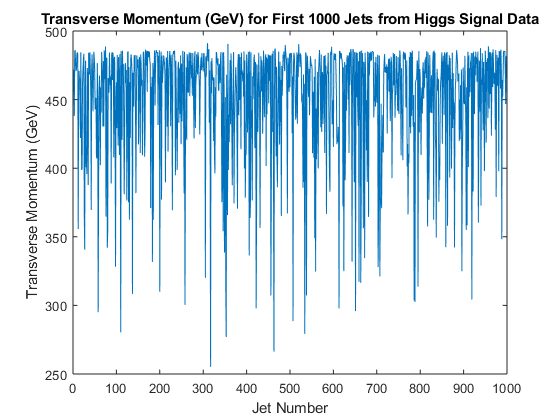

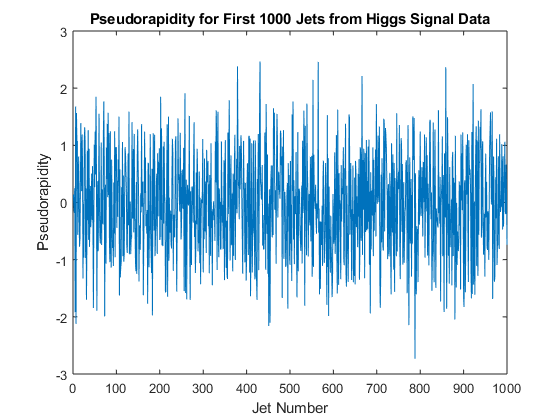

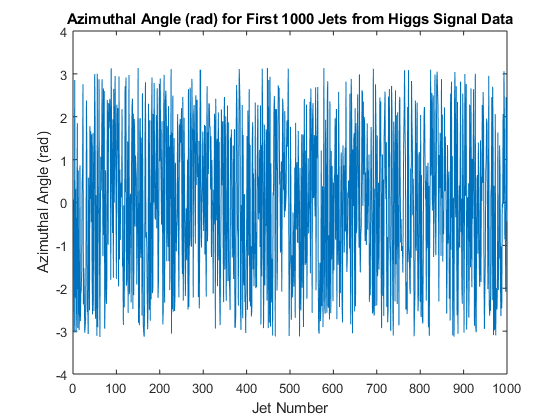

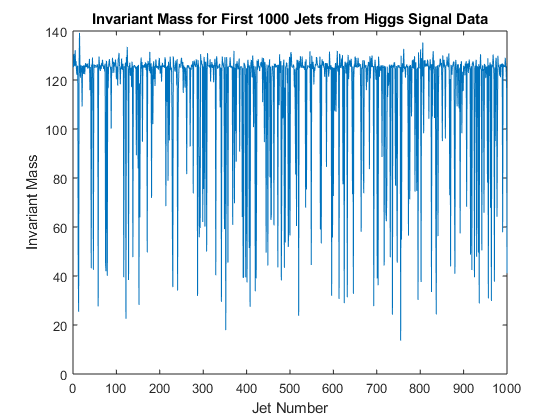

for i = 2:5 
    
    figure(i-1)
    plot(higgs{1:1000,i}); 
    xlabel('Jet Number'); 
    ylabel(VariableNames(i-1)); 
    title(VariableNames(i-1) + " for First 1000 Jets from Higgs Signal Data");    
    
end

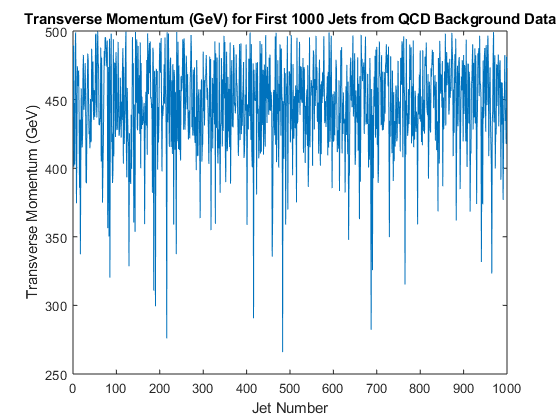

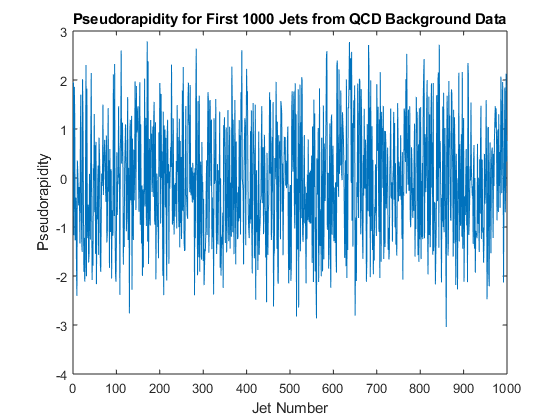

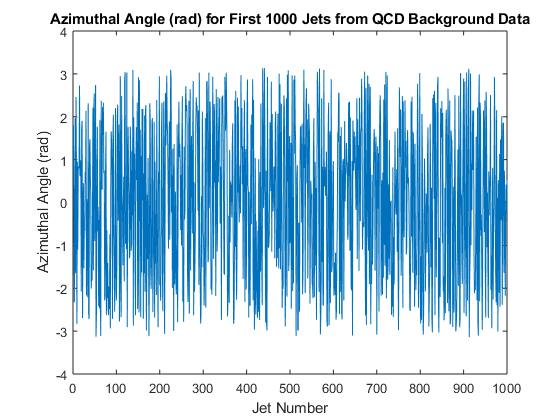

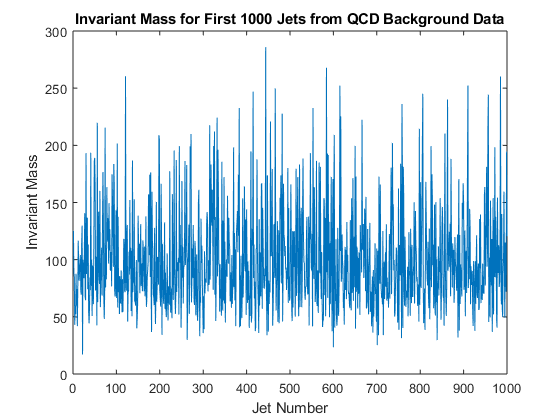

for i = 2:5
    
    figure(i+4)
    plot(qcd{1:1000,i}); 
    xlabel('Jet Number'); 
    ylabel(VariableNames(i-1)); 
    title(VariableNames(i-1) + " for First 1000 Jets from QCD Background Data");    
    
end

**From this preliminary data, we observe a few key things. It seems as if the transverse momentum measured for the first 1000 jets never exceeds roughly 500 GeV, while it looks like fairly narrow Gaussians comprise the rest of the data, explaining the relatively confined distribution except some sharp outliers. The pseudorapidity for both the Higgs and QCD data seems to be normally distributed around 0, which we would expect if we assumed that each collision was completely random and could produce a jet in any given direction. The same applies to the azimuthal angle measurements for both datasets. However, in the invariant mass datasets, we see significant difference between the Higgs and QCD measurements. For the QCD the invariant mass averages around 50-100 but experiences several sharp peaks to much higher values; the opposite shape takes place for the Higgs data, with a baseline at approximately 130 but with several deep plunges to as low as 20. However, we cannot claim any conclusions from this sample of 1000 out of 100000 jets to be indicative of the data trends for the entire dataset. In the following section, we plot histograms of these 4 variables for both the Higgs and QCD data, and try and fit distributions to each set. We then compare the distributions between the signal and background data, and attempt to reconcile them with physical explanations for what is actually happening inside the experiment.  **

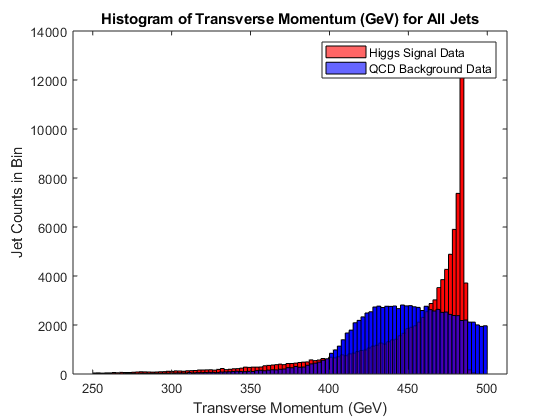

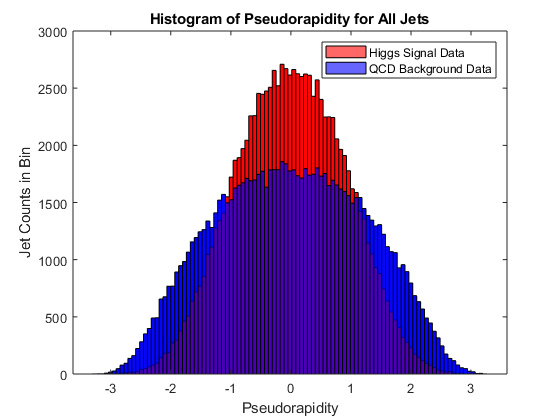

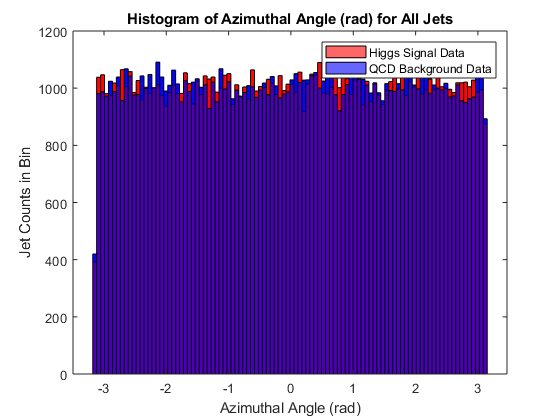

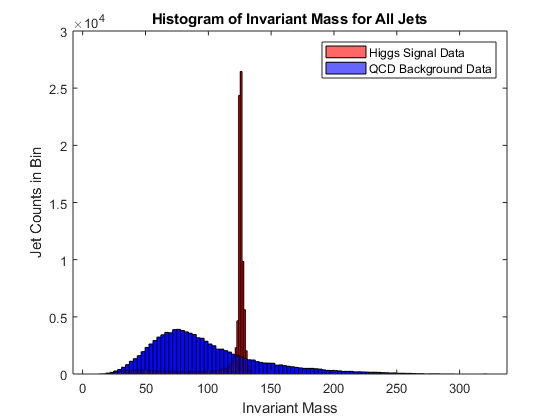

arr = []; 

for i = 2:5 
    
    figure(i+9)
    arr(:,i-1,1) = higgs{:,i}; 
    arr(:,i-1,2) = qcd{:,i}; 
    
    histogram(higgs{:,i},'FaceColor','Red',"NumBins",100); 
    hold on 
    histogram(qcd{:,i},'FaceColor','Blue',"NumBins",100);  
    xlabel(VariableNames(i-1)); 
    ylabel("Jet Counts in Bin"); 
    title("Histogram of " + VariableNames(i-1) + " for All Jets"); 
    legend("Higgs Signal Data","QCD Background Data");  
   
end


arr1 = arr(1:65536,:,1); 
arr2 = arr(1:65536,:,2); 

**Immediately, different trends show up when looking at all the data. Using the Matlab Distribution Filter application, the Higgs data for the Transverse Momentum measurements is most likely an Extreme Value distribution, but the QCD data yields no strong fits due to the curious fact that the momentum never exceeds 500 GeV, a conclusion that proves our connection from the 1000 jet sample data. The psuedorapidity for both jets follows a clearly Normal distribution, echoing our finds from the previous section as well. However, the histogram for the Azimuthal angle measurements shows an almost completely even spread of angles for the entire experiment. This is consistent with the jet taking truly random directions after the collision. For the psuedorapidity, we would *****not *****expect the same. Since the psuedorapidity describes the angle of the jet relative to the acual proton beam axis, and since the protons have almost all their momentum along this axis, we would expect the jets to only veer off in a direction close to this axis, since the momentum of each proton is almost exactly the same. This then explains the Normal distribution for the pseudorapidity, in contrast to the truly random distribution for the azimuthal angle. The histogram for the invariant mass is most interesting. The QCD background data looks like a slightly skewed Normal or potentially a Rayleigh distribution, while the Higgs data looks like an extremely concentrated Gaussian or Normal function. However, it seems as if such a narrow Gaussian distribution should be extremely unlikely. Either this extremely sharp peak is described by a different distribution entirely, or there is a driving physical mechanism that forces the Higgs signal invariant mass to be incredibly precise and well bounded. **

**TO DO/consider: add invariant masses? see how probability distributions change over # of jets tested (increments of a few k?) try and optimize fit from distribution filter, definitely more analysis of sharp peak in QCD invariant mass distribution + research into physical explanations for that, try and find better fits + physical explanations for the more unconventional distributions**

**TO DO: also add backgrounds and explanation for the general LHC experiment and more information on each of the variables being measured - i.e what is physically happening or being represented in each. **